CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('ContourData_S_EE=0.024_7D_HHigherRes_S_L6Modfd1.mat','ContourData_7D')

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ContourData_7D.C_EE;

C_EI = ContourData_7D.C_EI;

C_IE = ContourData_7D.C_IE;

C_II = ContourData_7D.C_II;

## The 2nd one of S_Ilgn: MF Contour Plot

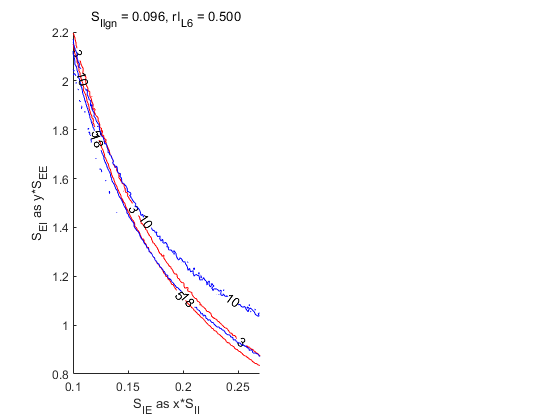

S_EEnow = ContourData_7D.S_EE;
S_IInow = ContourData_7D.S_II;
figure('Name','Contour Validation')
S_IlgnInd = 2; S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
rI_L6Ind  = 1; rI_L6now  = ContourData_7D.rI_L6test(rI_L6Ind);
        
    subplot 121    
    hold on
    CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:,S_IlgnInd,rI_L6Ind));
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); 
    CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); 
    CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
    [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10 18],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
    rI_L6txt = sprintf('%.3f',rI_L6now);
    title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')

    %xlim([0.06 0.5])

## Set up Network Simulation

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
% load('Initials.mat')
%parameters
S_EE = ContourData_7D.S_EE; S_II = ContourData_7D.S_II; %S_IE and S_EI will be tested
p_EEFail = ContourData_7D.p_EEFail; S_amb = ContourData_7D.S_amb;

tau_ampa_R = ContourData_7D.tau_ampa_R; tau_ampa_D = ContourData_7D.tau_ampa_D;
tau_nmda_R = ContourData_7D.tau_nmda_R; tau_nmda_D = ContourData_7D.tau_nmda_D;
tau_gaba_R = ContourData_7D.tau_gaba_R; tau_gaba_D = ContourData_7D.tau_gaba_D;
tau_ref = ContourData_7D.tau_ref; % time unit is ms
dt = 0.1;
gL_E = ContourData_7D.gL_E;  Ve = ContourData_7D.Ve; S_Elgn = ContourData_7D.S_Elgn; 
rhoE_ampa = ContourData_7D.rhoE_ampa; rhoE_nmda = ContourData_7D.rhoE_nmda;
gL_I = ContourData_7D.gL_I;  Vi = ContourData_7D.Vi; S_Ilgn = S_Ilgnnow;             
rhoI_ampa = ContourData_7D.rhoI_ampa; rhoI_nmda = ContourData_7D.rhoI_nmda;

% LGN input
lambda_E = ContourData_7D.lambda_E; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = ContourData_7D.lambda_I; 

% Check amb. That's for differnet figures
rE_amb = ContourData_7D.rE_amb; rI_amb = ContourData_7D.rI_amb;
% L6 input
S_EL6 = ContourData_7D.S_EL6; rE_L6 = ContourData_7D.rE_L6;
%S_IL6 = ContourData_7D.S_IL6; 
rI_L6 = rI_L6now; %250hz for now

% Length of the interval %% Replace S_EI by testing values
EITestN = 5;
EITestN1 = 4;
%S_IEtest = [0.14,0.19]*S_II;
S_IEtest = [0.15]*S_II; % 0.15 0.20
S_IL6test =  1/3 * S_IEtest;
S_EItest = [];
S_EItest(1,:) = [linspace(1.45,1.55,EITestN)] *S_EE;    % 1.5 1.7
%S_EItest(2,:) = [linspace(1.1,1.3,EITestN)] *S_EE;    % 1.1 1.3

% E-to-E delay time
T_EEDly = 1; N_EEDly = floor(T_EEDly/dt);

## MF Estimation, repeat

cluster = gcp('nocreate');
if isempty(cluster)
    cluster = parpool([4 64]);
    cluster.IdleTimeout = 1200;
end

Fr_NoFix_ref = zeros(2,EITestN,length(S_IEtest));
mV_NoFix_ref = zeros(2,EITestN,length(S_IEtest));
Fr_NoFixVar_ref = zeros(2,EITestN,length(S_IEtest));
mV_NoFixVar_ref = zeros(2,EITestN,length(S_IEtest));
Fr_NoFixTraj_ref = cell(EITestN,length(S_IEtest));
mV_NoFixTraj_ref = cell(EITestN,length(S_IEtest));

loopCount_ref = zeros(EITestN,length(S_IEtest)); % count the number of loops
ConvIndi_ref = logical(loopCount_ref);
FailureIndicate = logical(loopCount_ref);

SampleNum = 100;
MaxNum = 500;
h = 1;
SimuT = 20*1e3;
tic
for S_IEInd = 1:length(S_IEtest)
    S_IE = S_IEtest(S_IEInd);
    S_EItestNow = S_EItest(S_IEInd,:);
    S_IL6 = S_IL6test(S_IEInd);
parfor S_EIInd = 1:length(S_EItestNow)
    S_EI = S_EItestNow(S_EIInd);
    tic
    [Fr_NoFixTraj_ref{S_EIInd,S_IEInd},mV_NoFixTraj_ref{S_EIInd,S_IEInd},...
        loopCount_ref(S_EIInd,S_IEInd),    ConvIndi_ref(S_EIInd,S_IEInd),...
        FailureIndicate(S_EIInd,S_IEInd)]...
                  = MeanFieldEst_BkGd_Indep_StepSize_ref_testL6(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            S_EL6,S_IL6,rE_L6,rI_L6,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,h,SimuT);
                                        
    toc
end
end

历时 19.373210 秒。
历时 18.902757 秒。
历时 19.514591 秒。
历时 19.343045 秒。
历时 11.944029 秒。


toc

历时 33.850666 秒。



for S_IEInd = 1:length(S_IEtest)
for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_ref(:,S_EIInd,S_IEInd) = mean(Fr_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    mV_NoFix_ref(:,S_EIInd,S_IEInd) = mean(mV_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_ref(:,S_EIInd,S_IEInd) = var(Fr_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_ref(:,S_EIInd,S_IEInd) = var(mV_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
end
end

## Network Simulation

S_EE = 0.024, S_EI = 0.0372, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

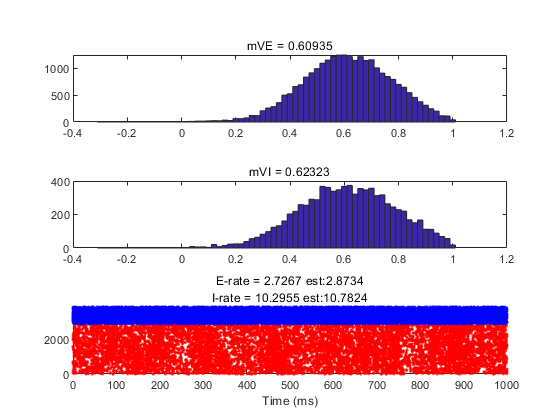

S_EE = 0.024, S_EI = 0.0372, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

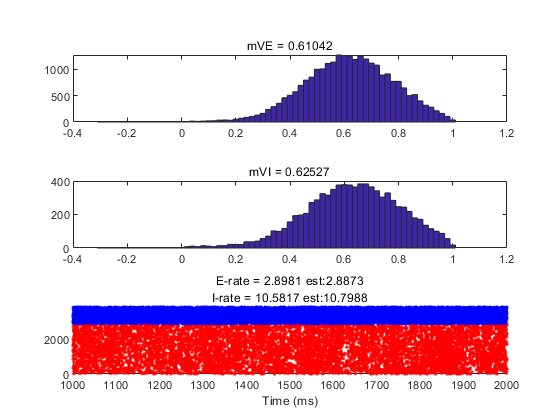

S_EE = 0.024, S_EI = 0.0366, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

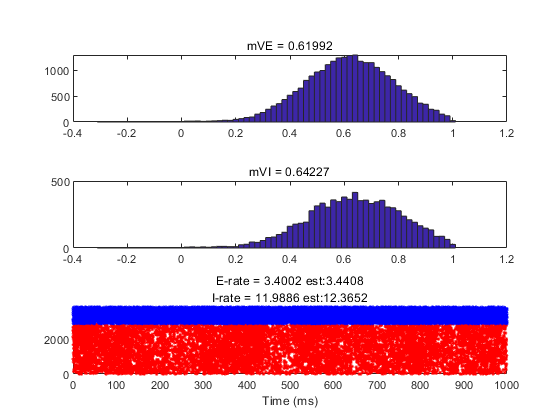

S_EE = 0.024, S_EI = 0.0366, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

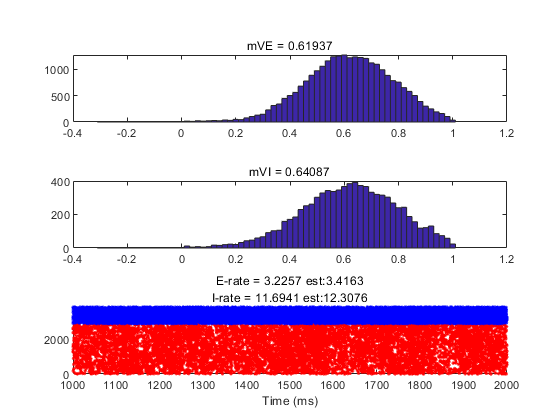

S_EE = 0.024, S_EI = 0.036, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

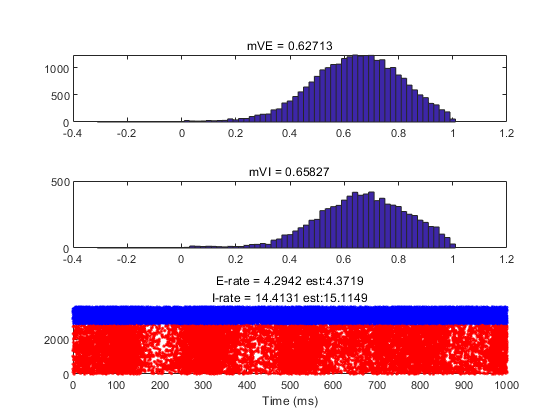

S_EE = 0.024, S_EI = 0.036, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

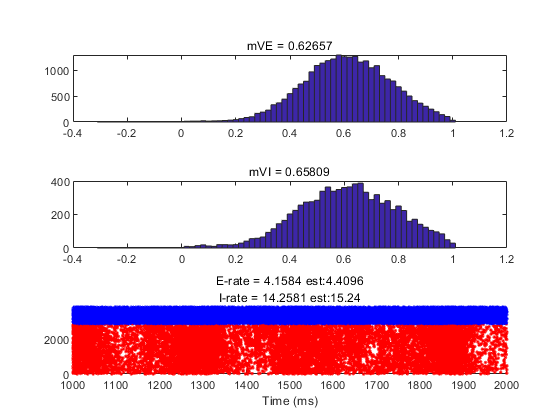

S_EE = 0.024, S_EI = 0.0354, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

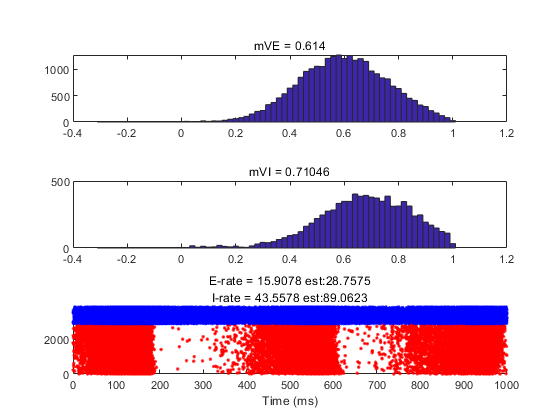

S_EE = 0.024, S_EI = 0.0354, S_IE = 0.018, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

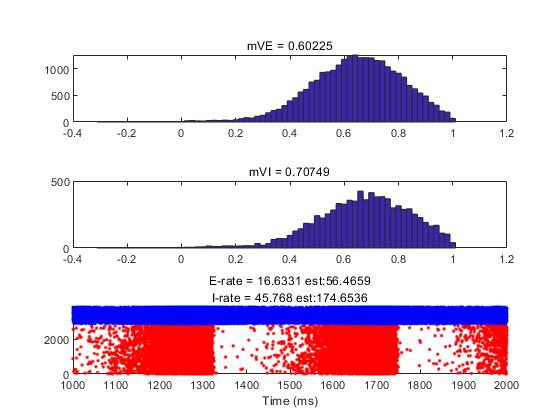

warning!: Network exploded


T = 2000; SimulationT = 1000;
% Setup Results Recording
Fr_NW      = zeros(2,EITestN,length(S_IEtest));
mV_NW      = zeros(2,EITestN,length(S_IEtest));
Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV
NWTraceAll = cell(EITestN,length(S_IEtest));

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));


sampleT = 20;
Sliding = 5;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% For each S Ind...
for S_IEInd = 1:length(S_IEtest)
    load('Initials_L6.mat')
    EEDlyRcd = sparse(N_E,N_EEDly);
    
    S_IE = S_IEtest(S_IEInd);
    S_IL6 = S_IL6test(S_IEInd);
    S_EItestNow = S_EItest(S_IEInd,:);
    BlowUp = false;
for S_EIInd = length(S_EItestNow):-1:1
    S_EI = S_EItestNow(S_EIInd);
    
    if BlowUp
    load('Initials_L6.mat')
    EEDlyRcd = sparse(N_E,N_EEDly);
    end
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    sampleN = floor(Sliding/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    
    BlowUp = false;
    SampleInd = 1;
    
    % Trace 1. Fr; 2. mV; 3. V distb
    NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
                 'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
    NWTrace.VEDist =  cell(size(Wins(:,1)));
    NWTrace.VIDist =  cell(size(Wins(:,1)));
    NWTrace.Wins = Wins;

    for TimeN = 1:floor(T/dt)
[oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                    oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                    oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                    oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                             GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                             RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                             GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                             EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                             C_EE,C_EI,C_IE,C_II,...
                             S_EE,S_EI,S_IE,S_II,...
                             tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                             dt,p_EEFail,...
                             gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                             gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                             S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
                             S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration                  
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
                                         
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure('Name','TestRaster');
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   S_EL6,S_IL6,rE_L6,rI_L6,...
                                   gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
    end 

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
    end
    
    NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp; 
    NWTraceAll{S_EIInd,S_IEInd} = NWTrace;
    
    % If blown up, discard other recordings...
    if BlowUp
        continue
    else        
        Fr_NW(:,S_EIInd,S_IEInd)      = [E_Rate;I_Rate];
        mV_NW(:,S_EIInd,S_IEInd)      = [nanmean(VE_T),nanmean(VI_T)];
        Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;        
    end
% end of S_IE loop    
end
% end of S_EI loop
end

GoodAreaFig = openfig([CurrentFolder '/Figures/Mf_7D_fine/GoodArea_S_IL6_Modfd.fig']);
subplot 231
ax1 = gca;
ax1_pos = ax1.Position;
ax2 = axes('Position',ax1_pos);
%%Link them together
linkaxes([ax1,ax2])
%%Hide the top axes
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];
colormap(ax2,mymap)
ax1.XLim = [0.1 0.27]; ax2.XLim = [0.1 0.27];
ax1.YLim = [0.8 2.2];  ax2.YLim = [0.8 2.2];

Accuracy = abs(Fr_NoFix_ref -Fr_NW)./Fr_NW;
c = max(Accuracy);
c(isnan(c)) = 1;
c(isinf(c)) = 1;
hold on
scatter(S_IEtest*ones(size(S_EItest))/S_II,S_EItest/S_EE,25,c,'filled')
hold off
colorbar
caxis([0, 0.4]);
mymap = [0 0 1
         0 1 1
         0 1 0
         1 0.5 0
         1 0 0
         1 0 1];
colorbar off

## Plot NW Dynamics

% % Compute Neuron Ind
% E_sideInd = floor(4/3*n_E_HC+1):floor(5/3*n_E_HC);
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
%     
% I_sideInd = floor(4/3*n_I_HC+1):floor(5/3*n_I_HC);
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

T_Plot = 800;

figure('Name','NWTrace')
for NWFigInd = 1:length(NWTraceAll)
    NWTraceNow =  NWTraceAll{NWFigInd};
    
    stdE = zeros(size(NWTraceNow.FrEs));
    stdI = zeros(size(NWTraceNow.FrEs));
    refE = zeros(size(NWTraceNow.FrEs));
    refI = zeros(size(NWTraceNow.FrEs));
    % Get Var of Vs
    for TInd = 1:length(NWTraceNow.VEDist)
        if isempty(NWTraceNow.VEDist{TInd})            
            continue
        end
        stdE(TInd) = nanstd(NWTraceNow.VEDist{TInd});
        stdI(TInd) = nanstd(NWTraceNow.VIDist{TInd});
        refE(TInd) = sum(isnan(NWTraceNow.VEDist{TInd})) / length(NWTraceNow.VEDist{TInd});
        refI(TInd) = sum(isnan(NWTraceNow.VIDist{TInd})) / length(NWTraceNow.VIDist{TInd});        
    end
    % A smaller domain
    scatterE = find(ismember(NWTraceNow.E_Sp(:,1),E_Ind));
    scatterI = find(ismember(NWTraceNow.I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(NWTraceNow.E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(NWTraceNow.I_Sp(scatterI,1),I_Ind);
    
    % raster plot
    subplot(5, length(NWTraceAll), NWFigInd)
    hold on
    scatter(NWTraceNow.E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(NWTraceNow.I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    xlabel('Time (ms)')
    xlim([0 T_Plot])
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    
    % firing rates
    subplot(5, length(NWTraceAll), NWFigInd + length(NWTraceAll))
    hold on
    plot(Wins(:,1), NWTraceNow.FrEs,'r','DisplayName','frE')
    plot(Wins(:,1), NWTraceNow.FrIs,'b','DisplayName','frI')
    legend;
    xlabel('Time (ms)'); ylabel('rates (Hz)')
    xlim([0 T_Plot])
    ylim([0 20])
    
    % mean Vs
    subplot(5, length(NWTraceAll), NWFigInd + 2*length(NWTraceAll))
    hold on
    plot(Wins(:,1), NWTraceNow.mVEs,'r','DisplayName','mVE')
    plot(Wins(:,1), NWTraceNow.mVIs,'b','DisplayName','mVI')
    legend;
    xlabel('Time (ms)'); ylabel('mV')
    xlim([0 T_Plot])
    ylim([0.55 0.75])  
    
    % stds
    subplot(5, length(NWTraceAll), NWFigInd + 3*length(NWTraceAll))
    hold on
    plot(Wins(:,1), stdE,'r','DisplayName','stdE')
    plot(Wins(:,1), stdI,'b','DisplayName','stdI')
    legend;
    xlabel('Time (ms)'); ylabel('std of dist')
    xlim([0 T_Plot])
    ylim([0.15 0.2])  
    
    % ref portions
    subplot(5, length(NWTraceAll), NWFigInd + 4*length(NWTraceAll))
    hold on
    plot(Wins(:,1), refE,'r','DisplayName','refE')
    plot(Wins(:,1), refI,'b','DisplayName','refI')
    legend;
    xlabel('Time (ms)'); ylabel('ref proportion')
    xlim([0 T_Plot])
    ylim([0 0.1]) 
    % clear scatterE scatterI E_Fire_Ind I_Fire_Ind
end

## See V dists

NWFigInd = 4;
NWTraceNow =  NWTraceAll{NWFigInd};
figure('Name','Distb')
for TInd = 1:length(NWTraceNow.VEDist)
    if isempty(NWTraceNow.VEDist{TInd})            
        break
    end
    subplot 211
    histogram(NWTraceNow.VEDist{TInd},0:0.05:1)
    title(sprintf('t = %.1f ms',TInd*Sliding))
    ylim([0 400])
    
    subplot 212
    histogram(NWTraceNow.VIDist{TInd},0:0.05:1)
    ylim([0 130])
    
    drawnow
    pause(0.2)
end

## HPC data validation figures

clear
CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/HPCData'])

S_EE = 0.024; S_Elgn = 0.036;
PX = 1; PY = 2;

load(sprintf('ContourData_Valid_S_EE=%.3f_S_Elgn=%.3f_7D_HPC_PX%d_PY%d.mat',S_EE,S_Elgn,...
                                                                            PX,  PY),...
     'ContourData_7D')

openfig([FigurePath sprintf('/Mf_7D_fine/GoodArea_S_Elgn=%.3f_rE.fig',S_Elgn)]);
subplot(4,5,PY+(PX-1)*5)
ax1 = gca;
ax1_pos = ax1.Position;
ax2 = axes('Position',ax1_pos);
%%Link them together
linkaxes([ax1,ax2])
%%Hide the top axes
ax2.Visible = 'off';
ax2.XTick = [];
ax2.YTick = [];
mymap = [0 0   1
         0 1   1
         0 1   0
         1 0.5 0
         1 0   0
         1 0   1];
colormap(ax2,mymap)
ax1.XLim = [0.1 0.27]; ax2.XLim = [0.1 0.27];
ax1.YLim = [0.8 2.2];  ax2.YLim = [0.8 2.2];

Accuracy = abs(ContourData_7D.Fr_NoFix_ref -ContourData_7D.Fr_NW)./ContourData_7D.Fr_NW;
c = squeeze(max(Accuracy));
c(isnan(c)) = 1;
c(isinf(c)) = 1;
Scatcl = c(:);
S_IEtestAll = ones(size(ContourData_7D.S_EItest(1,:)'))*ContourData_7D.S_IEtest;
ScatS_IE = S_IEtestAll(:);
S_EItestAll = ContourData_7D.S_EItest';
ScatS_EI = S_EItestAll(:);
hold on
scatter(ScatS_IE/ContourData_7D.S_II,ScatS_EI/S_EE,15,Scatcl,'filled')
hold off
colorbar
caxis([0, 0.4]);
colorbar off